Konfiguracija 1:


Skriti sloji: 10


Prenosna funkcija skritih slojev: tansig


Prenosna funkcija izhodnega sloja: purelin


Konfuzijska matrika (učni podatki):


   149     0
   250     0



Konfuzijska matrika (testni podatki):


     0     0     0
     1    62     0
     0   107     0



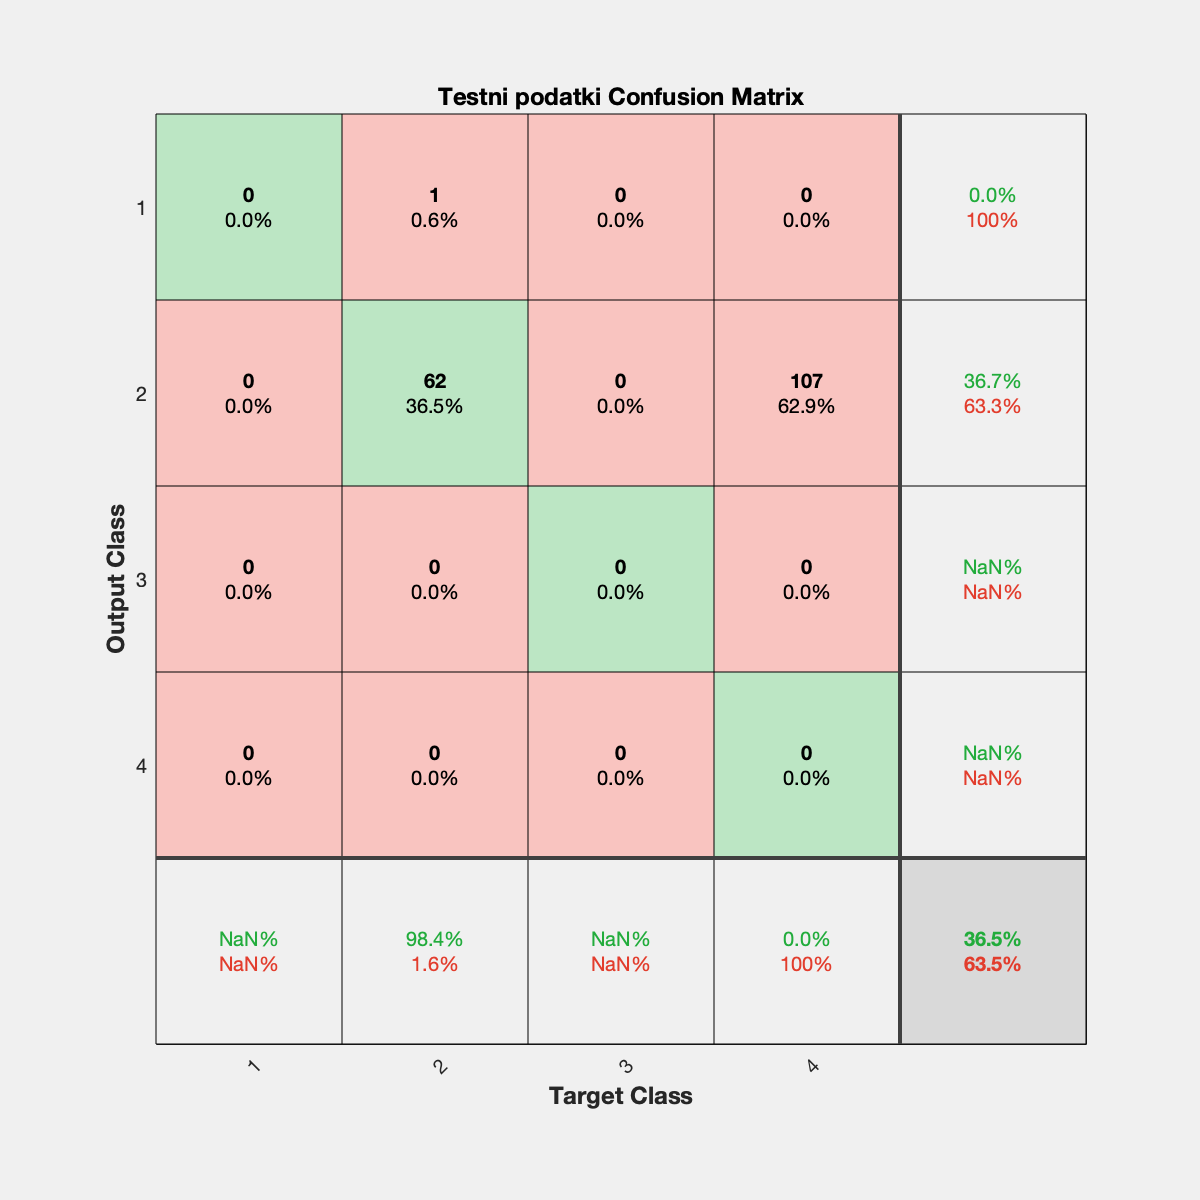

Konfiguracija 2:


Skriti sloji: [10 5]


Prenosna funkcija skritih slojev: tansig


Prenosna funkcija izhodnega sloja: tansig


Konfuzijska matrika (učni podatki):


   142     7
     4   246



Konfuzijska matrika (testni podatki):


    58     5
     3   104



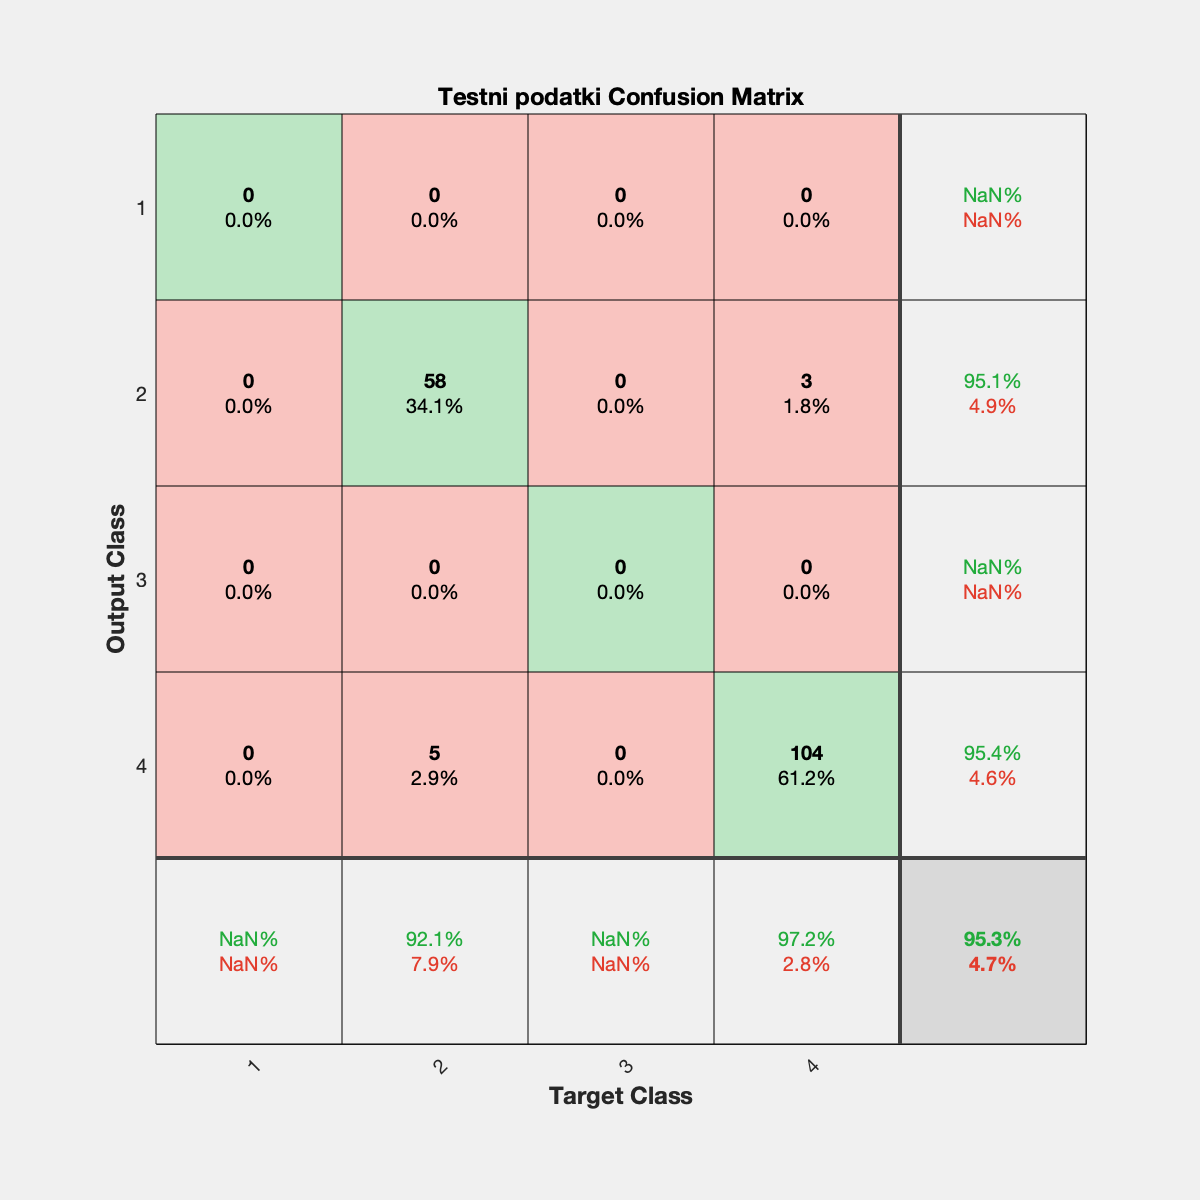

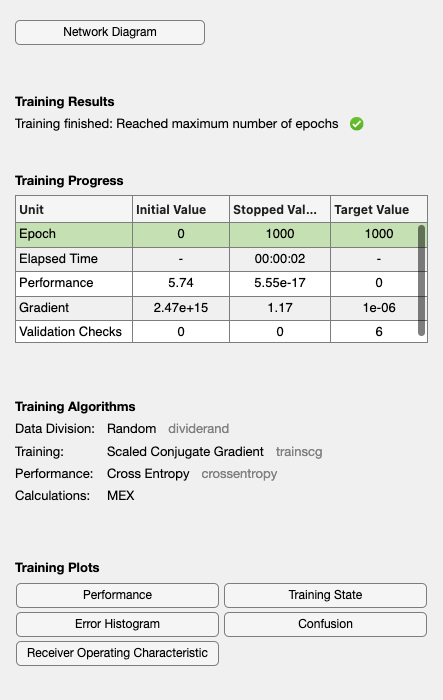

Konfiguracija 3:


Skriti sloji: 20


Prenosna funkcija skritih slojev: logsig


Prenosna funkcija izhodnega sloja: purelin


Konfuzijska matrika (učni podatki):


     0   149
     0   250



Konfuzijska matrika (testni podatki):


     0    63
     0   107



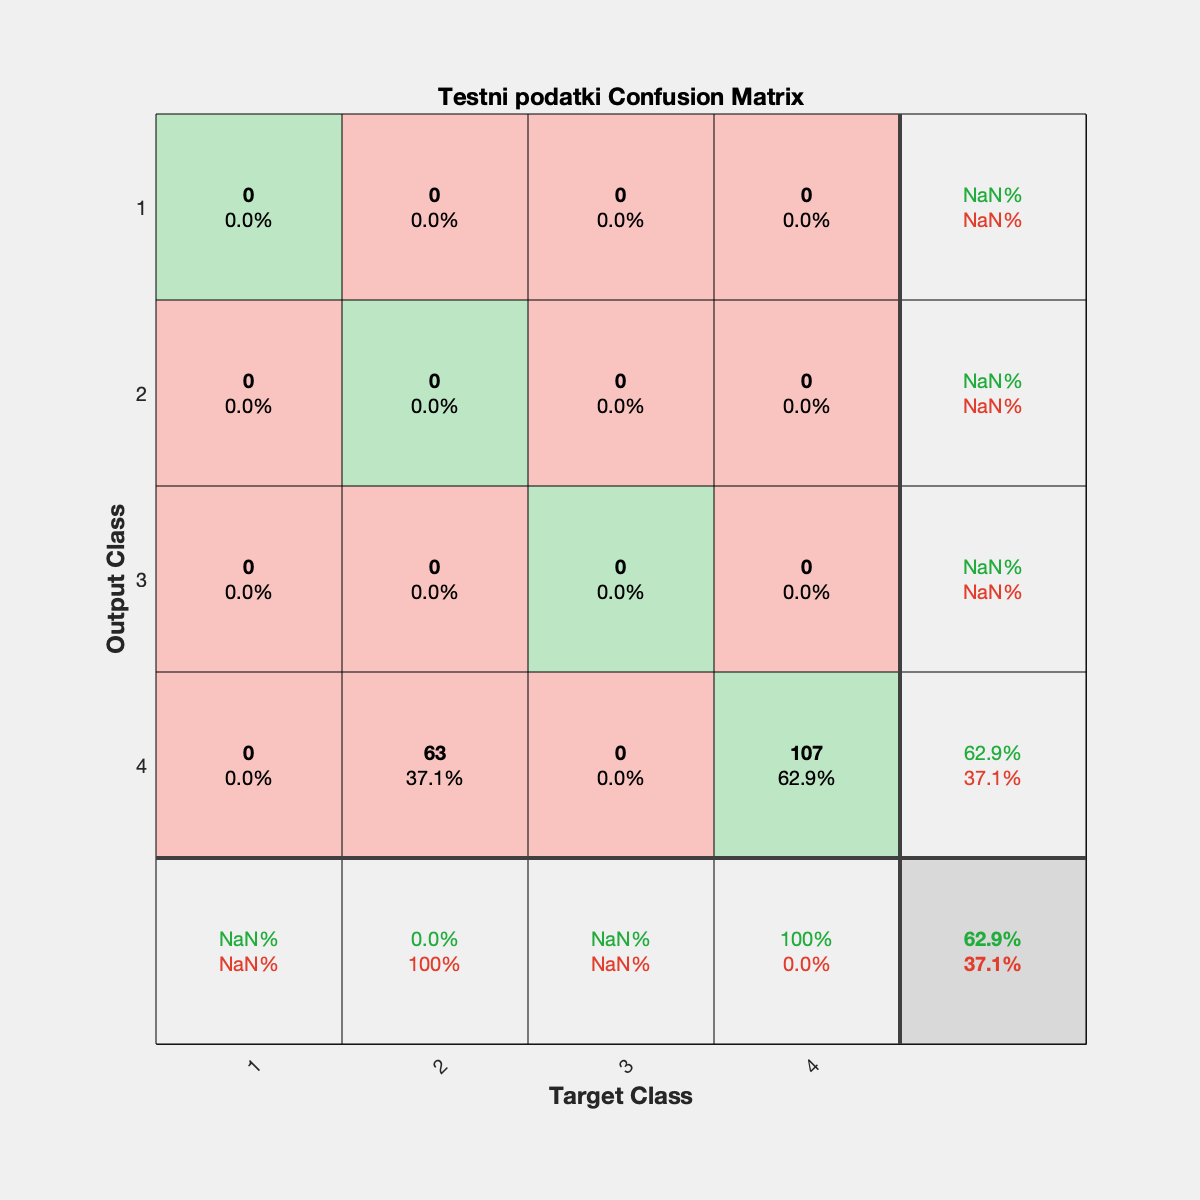

% Nalaganje podatkov
load('data.mat');

% razdelimo podatke na razrede in značilke
labels = data(:, 1);    % prvi stolpec so oznake razredov - labli
features = data(:, 2:end); % ostali stolpci so značilke

% Set the proportion of the data to be used for testing
testProportion = 0.3;
n = length(labels); % Total number of samples

% Generate a random permutation of the indices
perm = randperm(n);

% Determine the split index
splitIndex = round((1 - testProportion) * n);

% Split the data into training and testing sets
trainIndices = perm(1:splitIndex);
testIndices = perm(splitIndex+1:end);

trainData = data(trainIndices, :);
testData = data(testIndices, :);

% razdelimo podatke v testni in trening množici
trainFeatures = trainData(:, 2:end)';
trainLabels = trainData(:, 1)'; % Pravilno nastavi stolpce za oznake
testFeatures = testData(:, 2:end)';
testLabels = testData(:, 1)'; % Pravilno nastavi stolpce za oznake

% Normalizacija podatkov
[trainFeatures, mu, sigma] = zscore(trainFeatures'); % normaliziramo podatke na povprečje 0, standardni odklon 1
% mu in sigma sta povprečje in standardni odklon značilk
trainFeatures = trainFeatures';
testFeatures = (testFeatures' - mu) ./ sigma; % normiranje
testFeatures = testFeatures';

% Pretvorba oznak v binarno obliko (v binarne vektorje)
trainLabelsVec = ind2vec(trainLabels);
testLabelsVec = ind2vec(testLabels);

% Definicija mreže (več možnih konfiguracij)
configs = {
    {[10], 'tansig', 'purelin'}; % 1 skriti sloj z 10 nevroni
    {[10, 5], 'tansig', 'tansig'}; % 2 skrita sloja (10, 5 nevronov)
    {[20], 'logsig', 'purelin'}; % 1 skriti sloj z 20 nevroni
};

for i = 1:length(configs)
    % konfiguracija posamezne nevronske mreže
    config = configs{i};
    hiddenLayerSizes = config{1}; % velikost skritih layerjev  
    hiddenTransferFcn = config{2}; % prenosna funkcija skritih layerjev
    outputTransferFcn = config{3}; % prenosna funkcija izhodnega layerja

    % Ustvarjanje mreže
    net = patternnet(hiddenLayerSizes);
    net.layers{1}.transferFcn = hiddenTransferFcn;
    net.layers{2}.transferFcn = outputTransferFcn;

    % Delitev podatkov v MATLAB formatu
    net.divideFcn = 'dividerand';
    net.divideMode = 'sample';
    net.divideParam.trainRatio = 0.7;
    net.divideParam.valRatio = 0.15;
    net.divideParam.testRatio = 0.15;

    % Učenje mreže
    net = train(net, trainFeatures, trainLabelsVec);

    % Testiranje mreže
    predTrain = net(trainFeatures);
    predTest = net(testFeatures);

    % Pretvorba rezultatov v binarno obliko
    [~, predTrainClass] = max(predTrain, [], 1);
    % išče indeks z največjo vrednostjo v koloni (napovedani razred) za učne podatke
    [~, predTestClass] = max(predTest, [], 1);
    % išče indeks za največjo vrednost v koloni (-//-) za testne podatke

    % Analiza rezultatov
    trainConfMat = confusionmat(vec2ind(trainLabelsVec), predTrainClass);
    testConfMat = confusionmat(vec2ind(testLabelsVec), predTestClass);

    % Izpis rezultatov
    fprintf('Konfiguracija %d:\n', i);
    fprintf('Skriti sloji: %s\n', mat2str(hiddenLayerSizes));
    fprintf('Prenosna funkcija skritih slojev: %s\n', hiddenTransferFcn);
    fprintf('Prenosna funkcija izhodnega sloja: %s\n', outputTransferFcn);
    fprintf('Konfuzijska matrika (učni podatki):\n');
    disp(trainConfMat);
    fprintf('Konfuzijska matrika (testni podatki):\n');
    disp(testConfMat);

    % Risanje konfuzijske matrike
    figure;
    plotconfusion(trainLabelsVec, predTrain, 'Učni podatki');
    plotconfusion(testLabelsVec, predTest, 'Testni podatki');

    % Calculation of accuracy
    trainAccuracy = sum(diag(trainConfMat)) / sum(trainConfMat(:));
    testAccuracy = sum(diag(testConfMat)) / sum(testConfMat(:));
    
    % Display accuracy
    fprintf('Accuracy (Training Data): %.2f%%\n', trainAccuracy * 100);
    fprintf('Accuracy (Testing Data): %.2f%%\n', testAccuracy * 100);

end

% PSO optimizacija

% Load Data
load('data.mat');

% Split the data into labels and features
labels = data(:, 1);    % first column are the class labels
features = data(:, 2:end); % other columns are features

% Set the proportion of the data to be used for testing
testProportion = 0.3;
n = length(labels); % Total number of samples

% Generate a random permutation of the indices
perm = randperm(n);

% Determine the split index
splitIndex = round((1 - testProportion) * n);

% Split the data into training and testing sets
trainIndices = perm(1:splitIndex);
testIndices = perm(splitIndex+1:end);

trainData = data(trainIndices, :);
testData = data(testIndices, :);

% Split the data into training and testing sets
trainFeatures = trainData(:, 2:end)';
trainLabels = trainData(:, 1)'; % Correctly set columns for labels
testFeatures = testData(:, 2:end)';
testLabels = testData(:, 1)'; % Correctly set columns for labels

% Normalize the data
[trainFeatures, mu, sigma] = zscore(trainFeatures'); % Normalize data to mean 0, std 1
trainFeatures = trainFeatures';
testFeatures = (testFeatures' - mu) ./ sigma; % Normalize
testFeatures = testFeatures';

% Convert labels to binary form
trainLabelsVec = ind2vec(trainLabels);
testLabelsVec = ind2vec(testLabels);

% PSO parameters
nParticles = 30;
nIterations = 100;
c1 = 1.5; % Cognitive (particle) weight
c2 = 1.5; % Social (swarm) weight
w = 0.5;  % Inertia weight

% Neural network configuration
hiddenLayerSize = 10; % Number of neurons in hidden layer
inputSize = size(trainFeatures, 1);
outputSize = size(trainLabelsVec, 1);

% Initialize particles
particlePosition = randn(nParticles, inputSize * hiddenLayerSize + hiddenLayerSize * outputSize + hiddenLayerSize + outputSize);
particleVelocity = zeros(size(particlePosition));
pBest = particlePosition;
gBest = particlePosition(1, :);

% Fitness evaluation function
fitnessFunction = @(particle) evaluateFitness(particle, trainFeatures, trainLabelsVec, inputSize, hiddenLayerSize, outputSize);

% Evaluate initial fitness
pBestFitness = arrayfun(fitnessFunction, num2cell(pBest, 2));
[~, gBestIdx] = min(pBestFitness);
gBest = pBest(gBestIdx, :);

% PSO main loop
for iter = 1:nIterations
    for i = 1:nParticles
        % Update velocity
        particleVelocity(i, :) = w * particleVelocity(i, :) ...
                                + c1 * rand * (pBest(i, :) - particlePosition(i, :)) ...
                                + c2 * rand * (gBest - particlePosition(i, :));
                            
        % Update position
        particlePosition(i, :) = particlePosition(i, :) + particleVelocity(i, :);
        
        % Evaluate fitness
        currentFitness = fitnessFunction(particlePosition(i, :));
        
        % Update personal best
        if currentFitness < pBestFitness(i)
            pBest(i, :) = particlePosition(i, :);
            pBestFitness(i) = currentFitness;
        end
    end
    
    % Update global best
    [minFitness, minIdx] = min(pBestFitness);
    if minFitness < min(pBestFitness)
        gBest = pBest(minIdx, :);
    end
    
    fprintf('Iteration %d/%d, Best Fitness: %.4f\n', iter, nIterations, minFitness);
end

% Use gBest to set the weights of the neural network
net = patternnet(hiddenLayerSize);
net = configure(net, trainFeatures, trainLabelsVec);

% Set the weights of the neural network
net.IW{1, 1} = reshape(gBest(1:inputSize * hiddenLayerSize), hiddenLayerSize, inputSize);
net.LW{2, 1} = reshape(gBest(inputSize * hiddenLayerSize + 1:inputSize * hiddenLayerSize + hiddenLayerSize * outputSize), outputSize, hiddenLayerSize);
net.b{1} = gBest(inputSize * hiddenLayerSize + hiddenLayerSize * outputSize + 1:inputSize * hiddenLayerSize + hiddenLayerSize * outputSize + hiddenLayerSize);
net.b{2} = gBest(inputSize * hiddenLayerSize + hiddenLayerSize * outputSize + hiddenLayerSize + 1:end);

% Evaluate performance
predTrain = net(trainFeatures);
predTest = net(testFeatures);

[~, predTrainClass] = max(predTrain, [], 1);
[~, predTestClass] = max(predTest, [], 1);

trainConfMat = confusionmat(vec2ind(trainLabelsVec), predTrainClass);
testConfMat = confusionmat(vec2ind(testLabelsVec), predTestClass);

% Display results
fprintf('Confusion Matrix (Training Data):\n');
disp(trainConfMat);
fprintf('Confusion Matrix (Testing Data):\n');
disp(testConfMat);

% Plot confusion matrices
figure;
plotconfusion(trainLabelsVec, predTrain, 'Training Data');
plotconfusion(testLabelsVec, predTest, 'Testing Data');

% Calculate and display accuracy
trainAccuracy = sum(diag(trainConfMat)) / sum(trainConfMat(:));
testAccuracy = sum(diag(testConfMat)) / sum(testConfMat(:));

fprintf('Accuracy (Training Data): %.2f%%\n', trainAccuracy * 100);
fprintf('Accuracy (Testing Data): %.2f%%\n', testAccuracy * 100);


function fitness = evaluateFitness(particle, trainFeatures, trainLabelsVec, inputSize, hiddenLayerSize, outputSize)
    % Reshape the particle to form the weights and biases of the neural network
    IW = reshape(particle(1:inputSize * hiddenLayerSize), hiddenLayerSize, inputSize);
    LW = reshape(particle(inputSize * hiddenLayerSize + 1:inputSize * hiddenLayerSize + hiddenLayerSize * outputSize), outputSize, hiddenLayerSize);
    b1 = particle(inputSize * hiddenLayerSize + hiddenLayerSize * outputSize + 1:inputSize * hiddenLayerSize + hiddenLayerSize * outputSize + hiddenLayerSize);
    b2 = particle(inputSize * hiddenLayerSize + hiddenLayerSize * outputSize + hiddenLayerSize + 1:end);

    % Create the neural network
    net = patternnet(hiddenLayerSize);
    net = configure(net, trainFeatures, trainLabelsVec);

    % Set the weights and biases
    net.IW{1, 1} = IW;
    net.LW{2, 1} = LW;
    net.b{1} = b1;
    net.b{2} = b2;

    % Evaluate the neural network
    predTrain = net(trainFeatures);

    % Calculate the cross-entropy loss
    performance = perform(net, trainLabelsVec, predTrain);

    % Fitness is the performance (lower is better)
    fitness = performance;
end


